% code to simulate effect of truncation length on average lifetime

clear variables
close all
clc


## generate single exponential decay

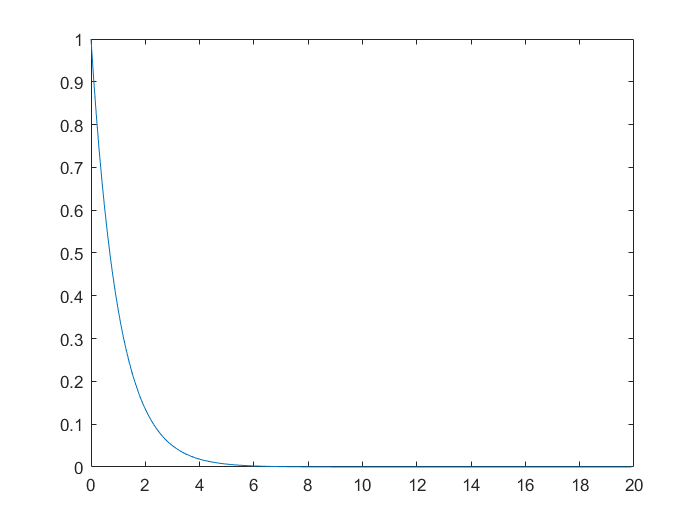

tau = 1; %ns
dt = 0.1; %ns
t = 0:dt:20*tau-dt;
decay = exp(-t/tau)';
figure
plot(t,decay)

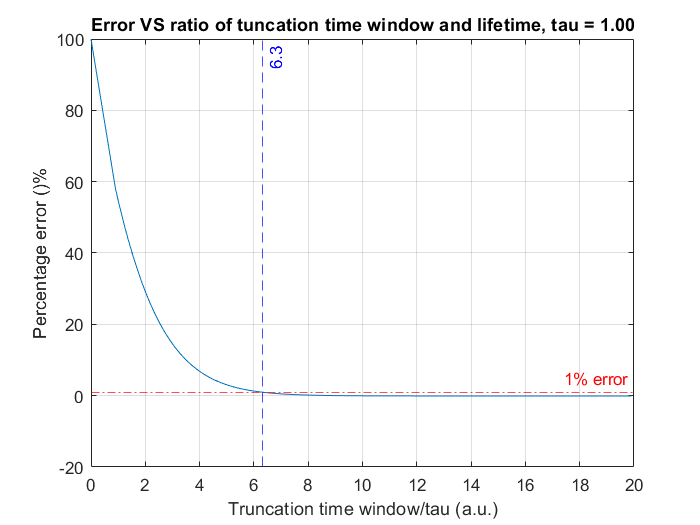


% compute average lifetime
T = zeros(size(t));
xx = zeros(size(t));
for i = 1/dt:length(t)
    temp = decay(1:i);
    T(i) = h_lifet(temp,dt,'average');
    xx(i) = t(i)/tau;
end
E = (tau-T)/tau*100;
idx = find(E-1<0,1);
figure
plot(xx,E)
grid on
yline(1,'r-.','1% error')
xline(xx(idx),'b--',num2str(xx(idx)))
ylabel('Percentage error ()%')
xlabel('Truncation time window/tau (a.u.)')
title(sprintf('Error VS ratio of tuncation time window and lifetime, tau = %.2f',tau))

## generate doubleexponential decay

tau1 = 3; %ns
tau2 = 16;
a1 = 0.1;
a2 = 1-a1;
dt = 0.1; %ns
t = 0:dt:20*tau2-dt;
decay = a1*exp(-t/tau1)'+a2*exp(-t/tau2)';
tauTrue = (a1*tau1^2+a2*tau2^2)/(a1*tau1+a2*tau2)

tauTrue = 15.7347

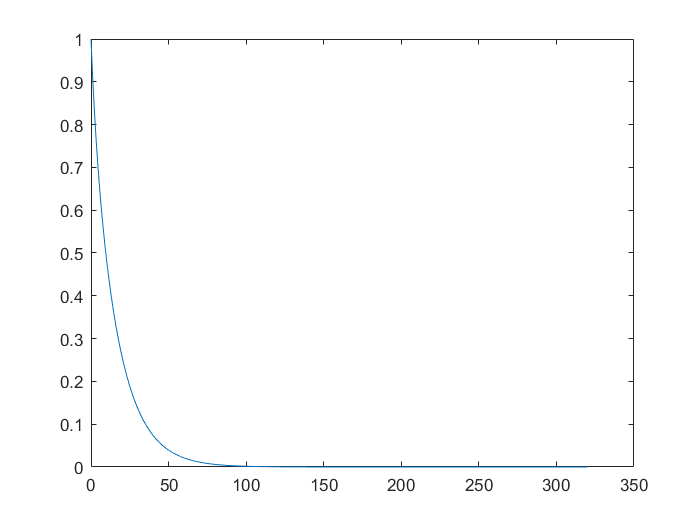

figure
plot(t,decay)

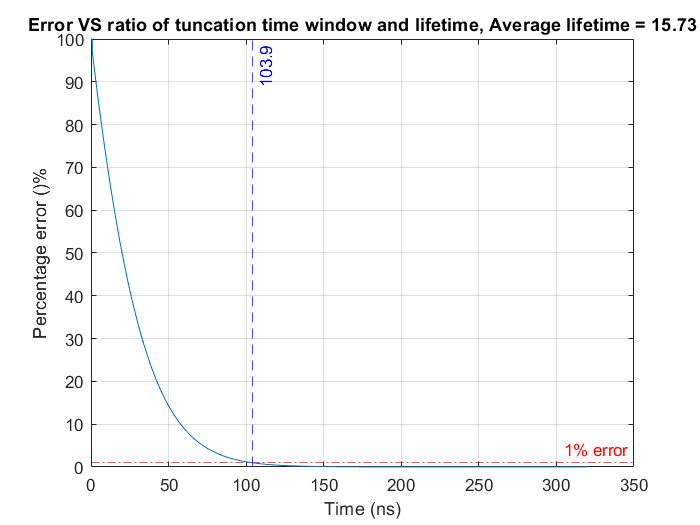


% compute average lifetime
T = zeros(size(t));
xx = zeros(size(t));
for i = 1/dt:length(t)
    temp = decay(1:i);
    T(i) = h_lifet(temp,dt,'average');
    xx(i) = t(i)/tauTrue;
end
E = (tauTrue-T)/tauTrue*100;
idx = find(E-1<0,1);
figure
plot(t,E)
grid on
yline(1,'r-.','1% error')
xline(t(idx),'b--',num2str(t(idx)))
ylabel('Percentage error ()%')
xlabel('Time (ns)')
title(sprintf('Error VS ratio of tuncation time window and lifetime, Average lifetime = %.2f',tauTrue))